# Writing MATLAB Code Without Writing MATLAB Code

This live script is a demonstration of a full data analysis workflow using many MATLAB features that automatically generate reusable code. These tools are very powerful for exploring and prototyping new tasks because they allow for rapid iteration of analysis methods.

 The dataset used in this demo is from: [AF Classification from a Short Single Lead ECG Recording - The PhysioNet Computing in Cardiology Challenge 2017](https://physionet.org/content/challenge-2017/1.0.0/). This dataset is also used in an[ example](https://www.mathworks.com/help/signal/ug/classify-ecg-signals-using-long-short-term-memory-networks.html) from the Deep Learning Toolbox. It is a collection of 8,528 electrocardiogram (ECG) recordings for the purpose of classying abnormal heart rate rhythms called arrhythmias.

The goal of this analysis is calculate variability in the RR interval, which is the time between the peak "R wave" of ECG signals (see figure below). There are multiple types of arrhythmias, but they often lack the regular rhythm found in normal ECGs, so there should be more variability in the RR interval on average. 

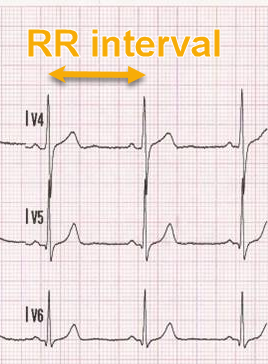

Source: [https://en.wikipedia.org/wiki/Electrocardiography#/media/File:12leadECG.jpg](https://en.wikipedia.org/wiki/Electrocardiography#/media/File:12leadECG.jpg)

## Import ECG Data

To get started, download and unzip the data files

if ~exist("training2017","dir")
    unzip("https://archive.physionet.org/challenge/2017/training2017.zip")
end

The data files in this dataset are in MAT-files, which can be loaded individually with the `load` command

fname = fullfile("training2017","A00001.mat")

fname = "training2017\A00001.mat"

load(fname,"val")

The workspace now contains a single ECG in the `val` variable. Alternatively, there is an interactive method that will generate an import function. Click "Import Data" in the toolstrip, locate one of the MAT-files, and select the "Generate MATLAB code" option while importing

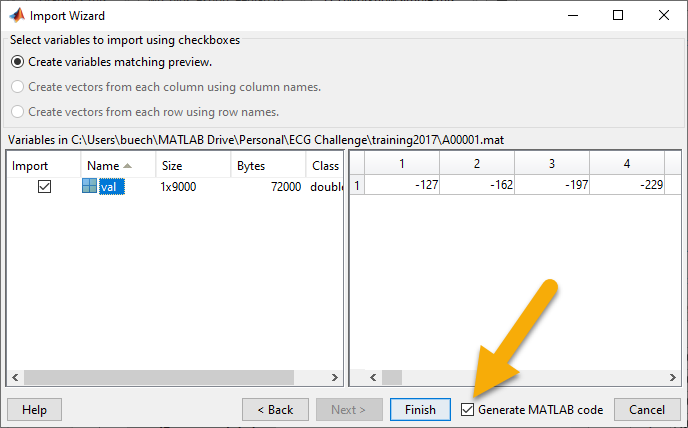

This will generate an import function, which is useful because that function can be used for *any* of the ECG files. The local function `importECG` at the bottom of this live script is an adapted version that organizes the data into a table. The reason for this will become clear later. For now, here is the output of the function for one file.

sampleECG = importECG(fname)

sampleECG = 9000×2 table
      ID      Value
    ______    _____

    A00001    -127 
    A00001    -162 
    A00001    -197 
    A00001    -229 
    A00001    -245 
    A00001    -254 
    A00001    -261 
    A00001    -265 
    A00001    -268 
    A00001    -268 
    A00001    -267 
    A00001    -265 
    A00001    -263 
    A00001    -260 
    A00001    -256 
    A00001    -253 


The table has two columns. The ECG itself is in the column Value, and the name for this file is in the categorical variable `ID`. This variable will be very useful once we've imported multiple files

## Import multiple files with a datastore

A datastore is a convenient way to import large collections of data. There are different types of datastores for datatypes like images and spreadsheets, but the code below uses a file datastore. This type can import any file where you provide a "read" function like `importECG`.

The code below will import all the ECG files using the `readall` method. The data is organized into a large single table, which is the reason we adapted `importECG` to load an ECG file into a table.

% Create a datastore for all the ECG files
ds = fileDatastore(fullfile("training2017","*.mat"), ...
    "ReadFcn",@importECG,"UniformRead",true)

ds =   FileDatastore with properties:

                       Files: {
                              ' ...\buech\MATLAB Drive\Personal\ECG Challenge\training2017\A00001.mat';
                              ' ...\buech\MATLAB Drive\Personal\ECG Challenge\training2017\A00002.mat';
                              ' ...\buech\MATLAB Drive\Personal\ECG Challenge\training2017\A00003.mat'
                               ... and 8525 more
                              }
                     Folders: {
                              'C:\Users\buech\MATLAB Drive\Personal\ECG Challenge\training2017'
                              }
                 UniformRead: 1
                    ReadMode: 'file'
                   BlockSize: Inf
                  PreviewFcn: @importECG
      SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"


% Read in ECG files
ds.Files = ds.Files(1:1000)

ds =   FileDatastore with properties:

                       Files: {
                              ' ...\buech\MATLAB Drive\Personal\ECG Challenge\training2017\A00001.mat';
                              ' ...\buech\MATLAB Drive\Personal\ECG Challenge\training2017\A00002.mat';
                              ' ...\buech\MATLAB Drive\Personal\ECG Challenge\training2017\A00003.mat'
                               ... and 997 more
                              }
                     Folders: {}
                 UniformRead: 1
                    ReadMode: 'file'
                   BlockSize: Inf
                  PreviewFcn: @importECG
      SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                     ReadFcn: @importECG
    AlternateFileSystemRoots: {}


ECG = ds.readall() 

ECG = 9868793×2 table
      ID      Value
    ______    _____

    A00001    -127 
    A00001    -162 
    A00001    -197 
    A00001    -229 
    A00001    -245 
    A00001    -254 
    A00001    -261 
    A00001    -265 
    A00001    -268 
    A00001    -268 
    A00001    -267 
    A00001    -265 
    A00001    -263 
    A00001    -260 
    A00001    -256 
    A00001    -253 


## Add in labels from a separate data file

The table `ECG` now has all of the ECGs, but we don't know which ECGs are labeled normal and which are labeled arrhythmic. This information is in the file "REFERENCE.csv", so we can import this separately and add to the ECG table.

First, use the Import Data tool to generate a script that loads the reference data.

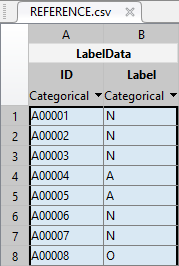        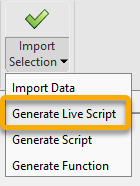

Call the script to load the file into the workspace. We could have instead used a function, but we only have one reference file to import.

importLabelData

LabelData = 8528×2 table
      ID      Label
    ______    _____

    A00001      N  
    A00002      N  
    A00003      N  
    A00004      A  
    A00005      A  
    A00006      N  
    A00007      N  
    A00008      O  
    A00009      A  
    A00010      N  
    A00011      N  
    A00012      N  
    A00013      O  
    A00014      N  
    A00015      A  
    A00016      N  


Then, use the **Join Tables** Live Task to join the label data and ECG table together. Live Tasks are miniature apps that run within a live script. They provide a useful interface to many data preprocessing functions and allow you to quickly explore different options. In this case, we can use a single `join` to add the `Label` variable to the ECG table

% Join tables
joinedData = join(ECG,LabelData,"Keys","ID")

joinedData = 9868793×3 table
      ID      Value    Label
    ______    _____    _____

    A00001    -127       N  
    A00001    -162       N  
    A00001    -197       N  
    A00001    -229       N  
    A00001    -245       N  
    A00001    -254       N  
    A00001    -261       N  
    A00001    -265       N  
    A00001    -268       N  
    A00001    -268       N  
    A00001    -267       N  
    A00001    -265       N  
    A00001    -263       N  
    A00001    -260       N  
    A00001    -256       N  
    A00001    -253       N  


Finally, use the interactive table preview to edit the categories, demonstrated in the GIF below.

- Remove the "O" and "~" categories

- Rename "N" cateogry to "Normal" and "A" to "Arrhythmia"

- Remove ECGs that are "<undefined>", which in this case are the ones formelrly labeled "O" and "~"

The code for these steps are generated below the table preview and can be added to the live script with the "Update Code" button.

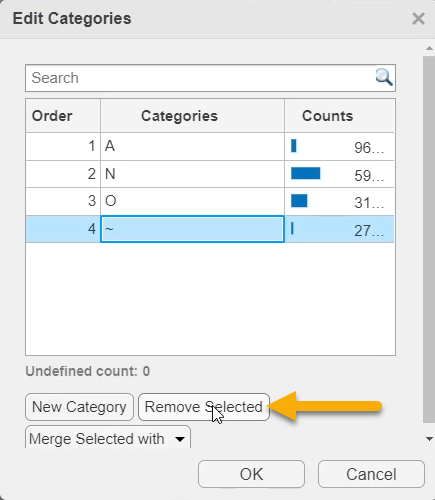   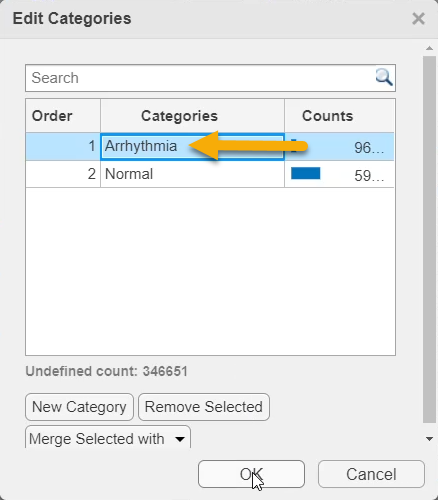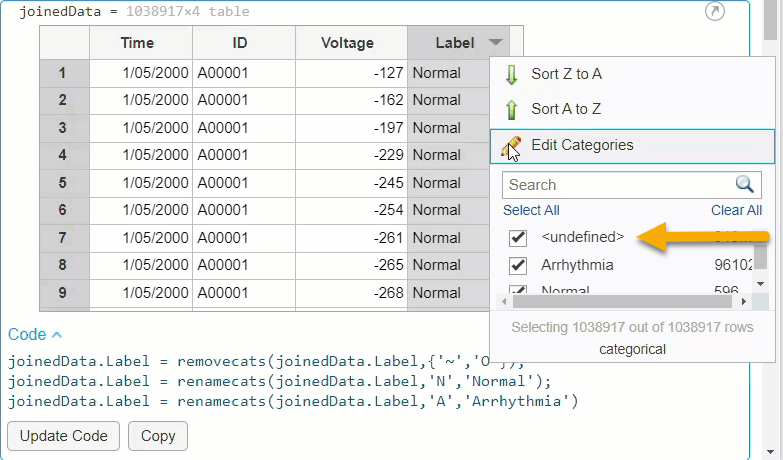

joinedData.Label = removecats(joinedData.Label,{'~','O'});
joinedData.Label = renamecats(joinedData.Label,'N','Normal');
joinedData.Label = renamecats(joinedData.Label,'A','Arrhythmia');
joinedData = joinedData(~ismissing(joinedData.Label),:)

joinedData = 6698500×3 table
      ID      Value    Label 
    ______    _____    ______

    A00001    -127     Normal
    A00001    -162     Normal
    A00001    -197     Normal
    A00001    -229     Normal
    A00001    -245     Normal
    A00001    -254     Normal
    A00001    -261     Normal
    A00001    -265     Normal
    A00001    -268     Normal
    A00001    -268     Normal
    A00001    -267     Normal
    A00001    -265     Normal
    A00001    -263     Normal
    A00001    -260     Normal
    A00001    -256     Normal
    A00001    -253     Normal


## Select a single ID for testing

Now that the data is unorganized, we can develop a method to calculate the variablility in the RR interval. It will help to test out methods on a single ECG, so we start by adding an interactive dropdown menu to select a single ECG

% Remove empty categories in ID variable. These are the IDs that 
% were labeled "~" and "O". This step is optional, but it helps 
% us avoid selecting an empty ECG in the dropdown menu.
joinedData.ID = removecats(joinedData.ID);

% Create a dropdown to select a single ECG
IDs = string(categories(joinedData.ID));
IDchoice = IDs(15)

IDchoice = "A00018"

Next, we extract out the ECG into a separate variable. This step is not strictly necessary, but it will help with the refactoring code step that we'll perform later.

% Extract out the ECG
rows = joinedData.ID == IDchoice;
Value = joinedData.Value(rows);

We can visualize this ECG by exploring the **Create Plot** Live Task. This task provides an interface to the many plotting functions in MATLAB. In this case, a simple plot will show us the ECG.

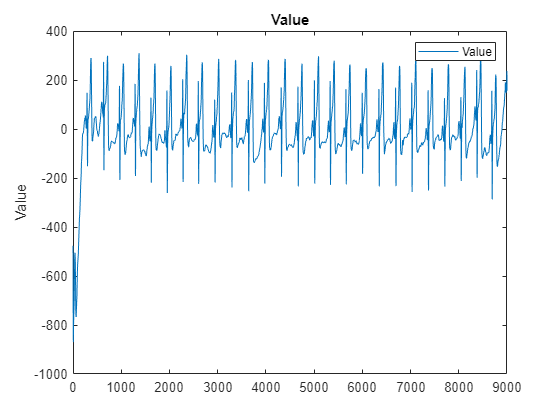

% Create plot of Value
h2 = plot(Value,'DisplayName','Value');

% Add ylabel, title, and legend
ylabel('Value')
title('Value')
legend

## Calculate RR-interval variation

Now we will identify the R peaks in the ECG. If you zoom in on the previous plot for file "A00018", you may see the sharp R waves but also prominent T waves. The T waves are not prominent in every ECG, but they present a problem for indentifying the R peaks in the waveforms.

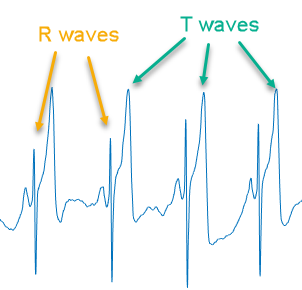

Because the R waves are so quick, we can emphsize them by taking the derivative of th ECG signal, specifically a first order difference. The code below accomplishes this with the `diff` function and visualizes the results with another Live Task.

% Get a time vector
sampleRate = 300;
Time = (0:length(Value)-1)/sampleRate;

% Calcualte 1st order difference
diffValue = [diff(Value); 0];


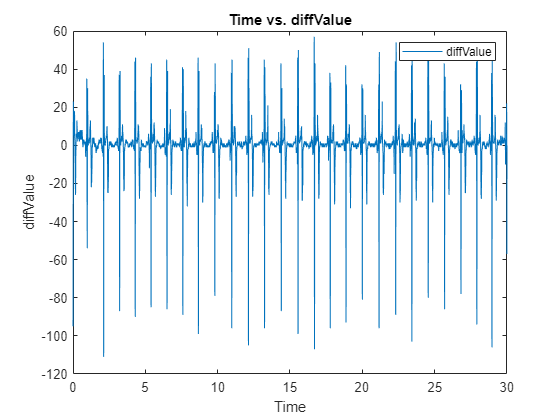

% Create plot of Time and diffValue
h = plot(Time,diffValue,'DisplayName','diffValue');

% Add xlabel, ylabel, title, and legend
xlabel('Time')
ylabel('diffValue')
title('Time vs. diffValue')
legend

Another useful preprocessing step for this task is normalizing the signals so the peaks have similar magnitudes across ECGs. We normalize the signal with the **Normalize Data **Live Task. We use the default option of a z-score, which subtracts the mean value and divides by the standard deviation.

% Normalize Data
normDiffValue = normalize(diffValue);

Now we can attempt to locate the peaks in the signal. We do this with the **Find Local Extrema** Live Task. We specify a couple of options to ensure we are only identifying the R waves:

- Min. separation = 75. This ensures that peaks are at least 75 samples apart, which translates to 250 ms. This upper cutoff will cap any detected heart rate at 240 bpm.

- Min. prominence = 3. This ensures the peaks have a "prominence" of at least 3 units, which is equal to 3 standard deviations since we normalized the signals with a z-score. See the documention for [`islocalmax`](https://www.mathworks.com/help/matlab/ref/islocalmax.html) for a more thorough description of "prominence".

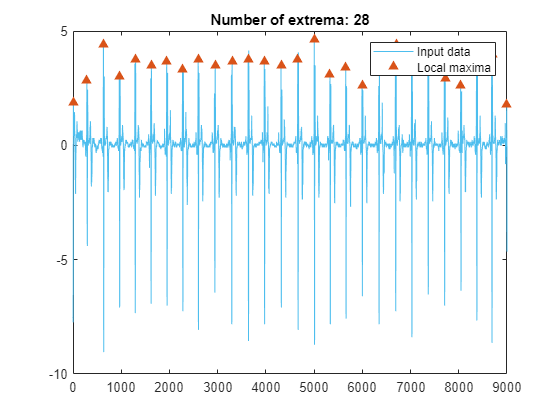

% Find local maxima
maxIndices = islocalmax(normDiffValue,"MinProminence",3,"MinSeparation",75);

% Display results
clf
plot(normDiffValue,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(find(maxIndices),normDiffValue(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices))
hold off
legend

The output visualization confirms we have suceesfully identified the R waves in the ECG.

The last step is to calculate the variability in the RR interval, which is the time between the identified peaks. We will calculate a value called the Coefficient of Variation, which is the standard deviation divided by the mean. Normalizing by the mean will help when the heart rates are very different between ECGs.

% Get time between R waves (RR intervals)
Rtimes = Time(maxIndices);
RRintervals = seconds(diff(Rtimes));

% Calculate the coefficient of variation
RRvariation = std(RRintervals)/mean(RRintervals)

RRvariation = 0.0549

## Refactor code into a function

The next step is to apply this workflow to each ECG. This is possible with a loop, but we'll demonstrate a method that requires minimal code writing. First, in each of the Live Tasks in the previous section, we convert them to editable code using the options menu. It may help to remove the visualizations since we will only need the calculation code.

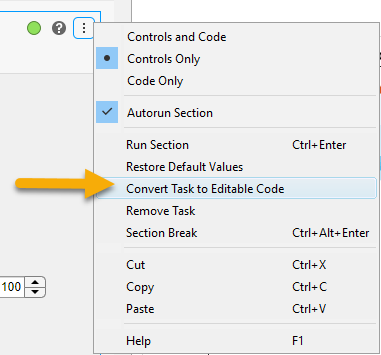

Then, highlight the section of code that calculates the RR variability. Right-click and select "Convert to Local Function"

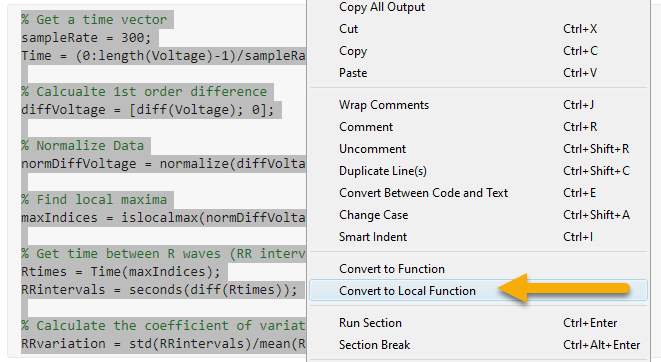

Name the function and set the output to be the `RRvariation` value. Check that this function returns the same value as before.

RRvariation2 = calcRRvariation(Value)

RRvariation2 = 0.0549

## Apply function across subjects

The newly created function can now be applied to each ECG. To accomplish this, insert a **Compute By Group** Live Task. You can use this task to calculate summary statistics for different groups in the data. In this case, the group is the ID, and the summary statistic is the RR variation. 

Select the variables `ID` and `Label` under "Group by". The `Label` isn't strictly necessary for the calculation, but it will be helpful in visualizing the results. Select `Value` as the variable for "Compute on". Then, add a custom function to "Computations per group" and select your function that calculates the RR variability.

% Compute group summary
results = groupsummary(joinedData,["ID","Label"],@calcRRvariation,"Value")

results = 691×4 table
      ID        Label       GroupCount    fun1_Value
    ______    __________    __________    __________

    A00001    Normal           9000        0.044383 
    A00002    Normal           9000         0.37727 
    A00003    Normal          18000         0.14398 
    A00004    Arrhythmia       9000         0.19179 
    A00005    Arrhythmia      18000         0.41251 
    A00006    Normal           9000        0.073749 
    A00007    Normal           9000         0.27928 
    A00009    Arrhythmia       9000         0.18416 
    A00010    Normal          18000        0.025503 
    A00011    Normal           9000         0.41545 
    A00012    Normal           9000        0.040253 
    A00014    Normal           5570         0.49714 
    A00015    Arrhythmia       6102          0.3234 
    A00016    Normal           9000        0.0

% Rename variable to something informative
results = renamevars(results,"fun1_Value","RRvariation")

results = 691×4 table
      ID        Label       GroupCount    RRvariation
    ______    __________    __________    ___________

    A00001    Normal           9000        0.044383  
    A00002    Normal           9000         0.37727  
    A00003    Normal          18000         0.14398  
    A00004    Arrhythmia       9000         0.19179  
    A00005    Arrhythmia      18000         0.41251  
    A00006    Normal           9000        0.073749  
    A00007    Normal           9000         0.27928  
    A00009    Arrhythmia       9000         0.18416  
    A00010    Normal          18000        0.025503  
    A00011    Normal           9000         0.41545  
    A00012    Normal           9000        0.040253  
    A00014    Normal           5570         0.49714  
    A00015    Arrhythmia       6102          0.3234  
    A00016    Normal           

The output is a table with a row for each ID in the dataset. The local function was applied to each group and returned the RR variability.

This completes the workflow, but we can visualize our results to see if they supported our hypothesis that Arrhythmias will have higher RR variability. Use about **Create Plot** Live Task and insert a `boxchart` plot. Use the label as the grouping data for make a boxplot for each group. 

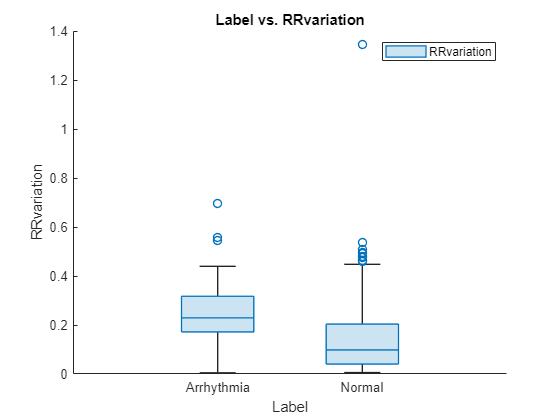

% Create boxchart of results.Label and results.RRvariation
h3 = boxchart(results.Label,results.RRvariation,'DisplayName','RRvariation');

% Add xlabel, ylabel, title, and legend
xlabel('Label')
ylabel('RRvariation')
title('Label vs. RRvariation')
legend

%ylim([0 1])

There are definitely outliers in the distributions, but zooming in on values between 0 and 1 shows that the RR variation is higher for ECGs with Arrhythmias. This supports our hypoethesis that the heart beats are more variable in the ECGs labeled as Arrhythmias.

## Takeaway

This script demonstrated numerous features that geneate code. Here's a list of all the features used in this script.

- Import Data tool - Generated `importECG` function to import single ECG files and `importLabelData` script to import the reference information

- **Join Data** Live Task - Generated code to merge the ECG table and reference information

- Edit Categories tool - Generated code to remove uneeded ECGs and organize the `Label` variable.

- Drop Down control - Interactive method to select individual ECGs (avoiding the need to hardcode each choice)

- **Create Plot** Live Task -  Generated code for multiple line plots and a boxchart plot.

- **Normalize Data** Live Task - Generated code to perform a z-score normalization

- **Find Local Extrema** Live Task - Generate code to find peaks in the ECG waveforms

- Refactoring code - Generated a function from exploratory code to calcute the RR variability

- **Compute by Group** Live Task - Generate code to apply a local function to each ECG in the  dataset

Insert summary here, e.g. these features demonstrate X, Y, Z.

## Appendix - Local functions

### `importECG - `Imports an ECG saved in a MAT-file

`ECG = importECG(filename)` loads a single ECG from a MAT-file and assembles it into a table with an ID extracted from the filename.

function T = importECG(filename)

% Load MAT-file to get the ECG waveform
data = load(filename);
Value = data.val';

% Get an ID vector
[~,ID,~] = fileparts(filename);
ID = categorical(repmat(string(ID),[length(Value) 1]));

% Assemble in table
T = table(ID,Value);

end

### `calcRRvariation` - Calculates variation in RR interval

`RRvariation = calcRRvariation(Value)` calculates the variation in the RR interval for an ECG vector in `Value`. Sampling rate is assumed to be 300 Hz.

function RRvariation = calcRRvariation(Value)

% Get a time vector
sampleRate = 300;
Time = (0:length(Value)-1)/sampleRate;

% Calcualte 1st order difference
diffValue = [diff(Value); 0];

% Normalize (Live Task)
diffValue = normalize(diffValue);

% Find local maxima (Live Task
maxIndices = islocalmax(diffValue,"MinProminence",3,...
    "MinSeparation",75);

Rtimes = Time(maxIndices);
RRintervals = seconds(diff(Rtimes));
RRvariation = std(RRintervals)/mean(RRintervals);
end